## Relatório Projeto 2 - Matemática Computacional

### 1

### a) e b)

format Long
t = [1 2 5 7 8 9 12]

t =      1     2     5     7     8     9    12


ft = [0.9 0.4 0.18 0.2 0.22 0.27 0.36]

ft =    0.900000000000000   0.400000000000000   0.180000000000000   0.200000000000000   0.220000000000000   0.270000000000000   0.360000000000000


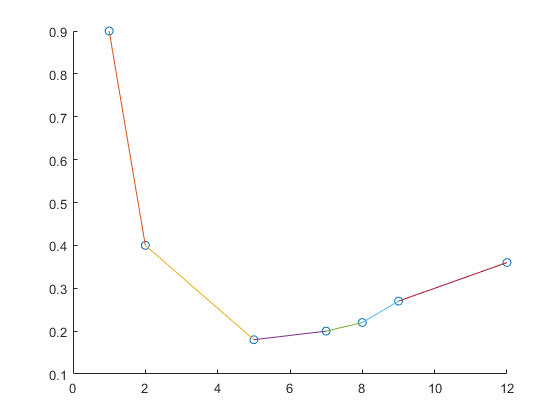

splinelinear(t,ft)

### c)

getvalue(t,ft,3)

ans =    0.340000000000000


A fórmula de erro para

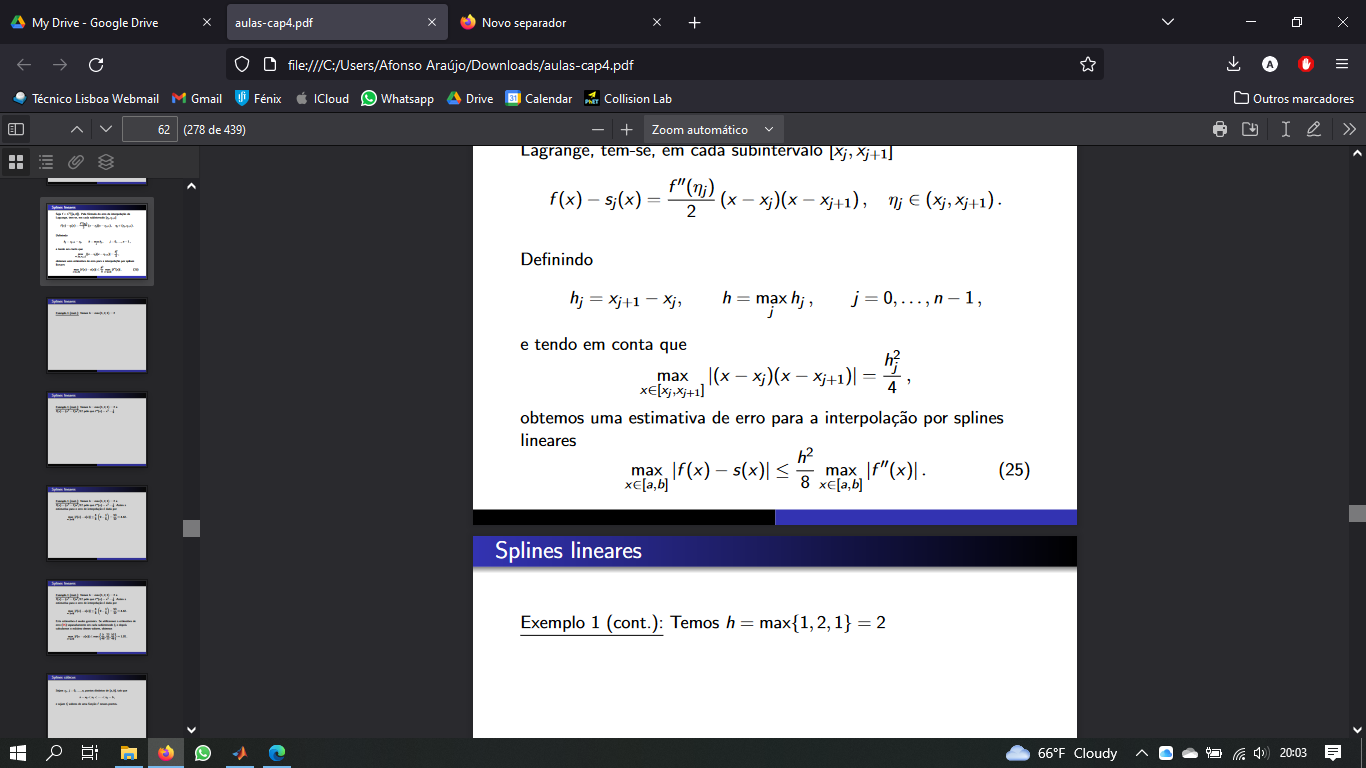

 0<f''(x)<1

calculamos os h para saber qual o máximo

%Descobrir o h máximo
n = numel(t)

n =      7


hmax = 0;
for i = 1:1:n-1
    if t(i+1)-t(i) > hmax
        hmax = t(i+1)-t(i);
    end
end

Considerando o pior dos casos para a 2 derivada de f no intervalo [1,12] podemos majorar o erro da seguinte forma:

M = ((hmax.^2)./8).*(1)

M =    1.125000000000000


Ainda assim este erro é muito grosseiro. Ao utilizar a fórmula de erro para cada subintervalo temos no ponto t=3:

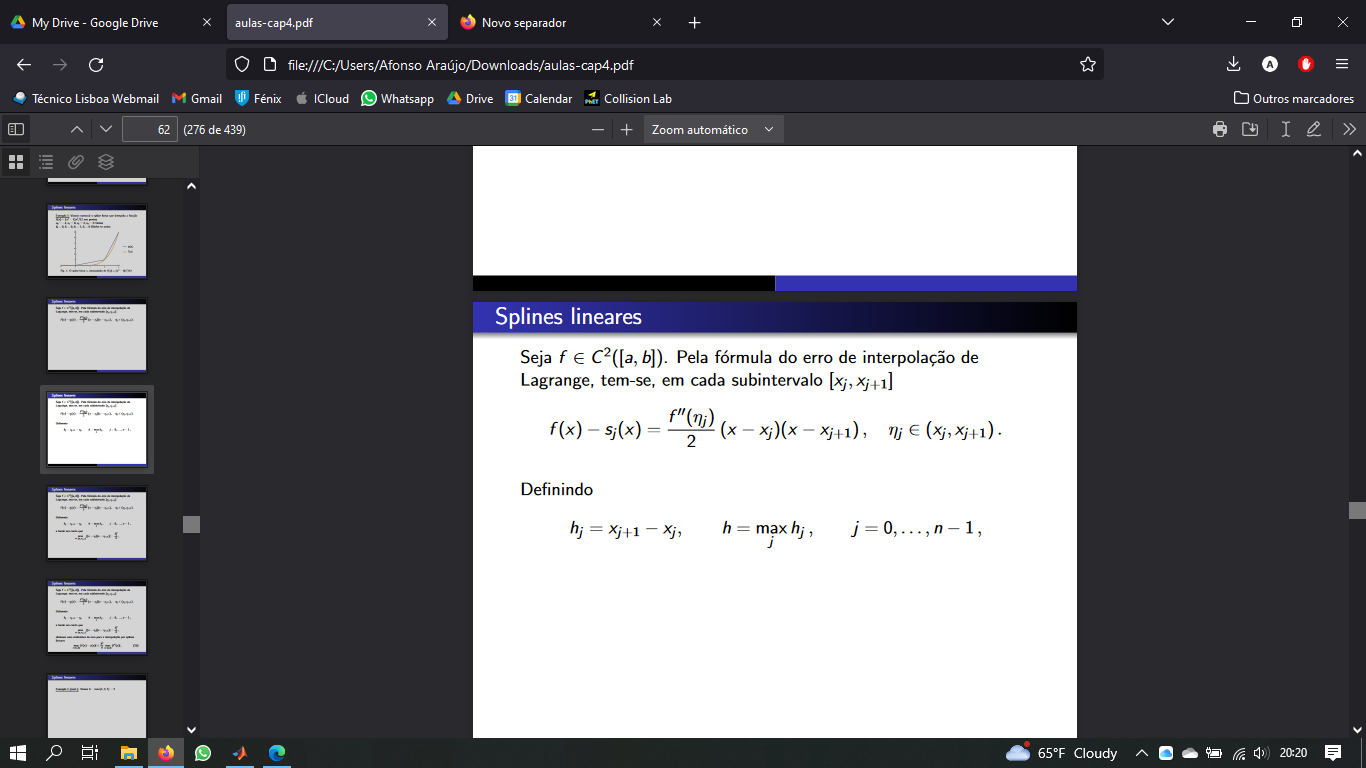

N = (1./2).*(3-2).*(3-5)

N =     -1


**Esta fórmula serve para aqui???**

### d)

Definem-se as funções de base

phi0 = @(t) exp(-3.*t)

phi0 = function_handle with value:
    @(t)exp(-3.*t)


phi1 = @(t) exp(0.1.*t)

phi1 = function_handle with value:
    @(t)exp(0.1.*t)


phi2 = @(t) exp(-t)

phi2 = function_handle with value:
    @(t)exp(-t)



coef = minq3(t,ft,phi0,phi1,phi2)

coef =    1.078218315985077
   0.104905974210165
   1.985444480853854



f = @(t) coef(1).*phi0(t) + coef(2).*phi1(t) + coef(3).*phi2(t)

f = function_handle with value:
    @(t)coef(1).*phi0(t)+coef(2).*phi1(t)+coef(3).*phi2(t)


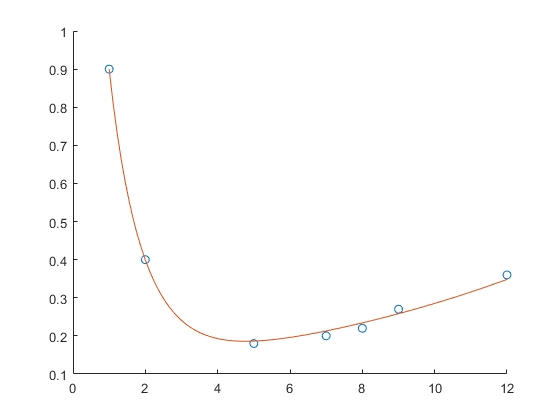


scatter(t,ft)
hold on
x = linspace(1,12,100);
plot(x,f(x))
hold off

### 2.

### a)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Trapcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' e'];
Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -0.056484191461176
   2.000060287256971


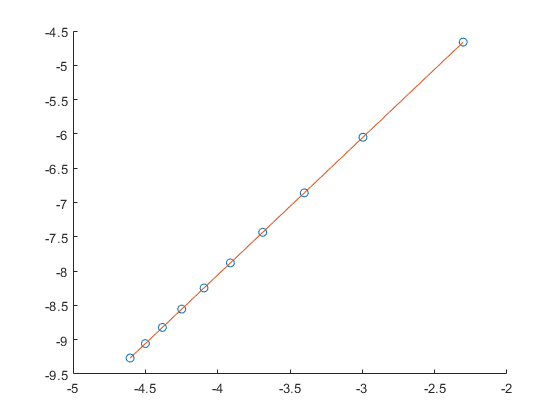

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
hold off

p = 2 justificar que é o coeficiente 

### b)

format long
volexact = 3.198423723387142

volexact =    3.198423723387142


g = @(x) pi.*(exp(-cos(x))).^2;
a = 1;
b = 2;

%Cálculo dos integrais para diferentes números de subintervalos
h = [];
v = [];
e = [];
ns = 10:10:100;
for i = 1:1:numel(ns)
    [v(i),h(i)] = Simpcomp(g,a,b,ns(i));
    e(i) = abs(v(i)-volexact);
end

%Representação gráfica do resultado linearizado
R = [ns' h' e'];
Rlin = [ns' log(h)' log(e)'];
scatter(Rlin(:,2), Rlin(:,3))
hold on

%Aproximação com mínimos quadrados
phi4 = @(t) (t == 0) .* 1 + (t ~= 0) .* 1;
phi5 = @(t) t;
coef = minq2(Rlin(:,2),Rlin(:,3),phi4,phi5)

coef =   -2.800377594103114
   3.986341214944837


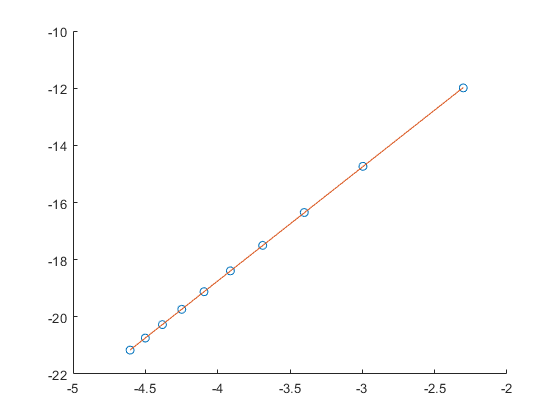

fminq = @(x) coef(1) + coef(2).*x;

%Gráfico da reta de aproximação
x = linspace(Rlin(1,2),Rlin(end,2),100);
plot(x, fminq(x))
hold off

p =~ 4 justificar a diferença dos ps nos diferentes métodos

### c)

Queremos Erro de V < 10e-7

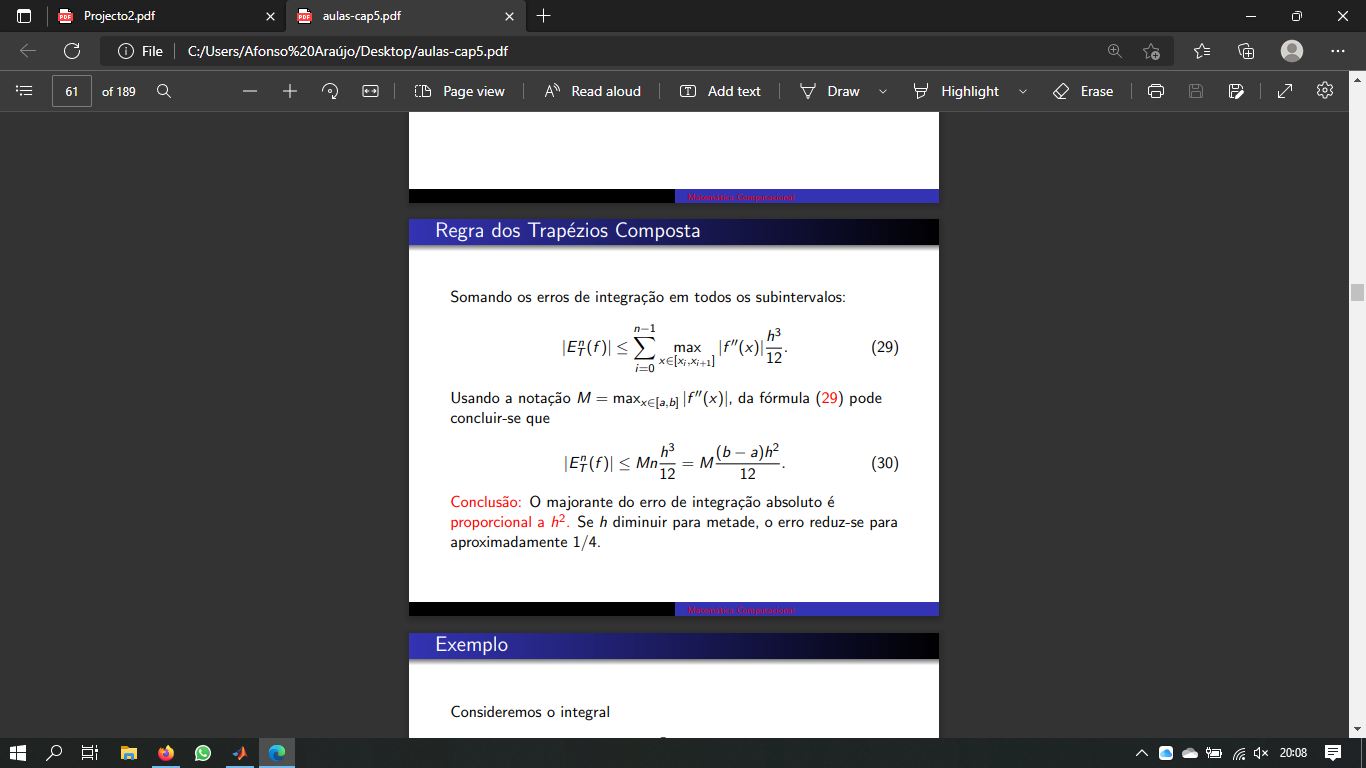

a=1;
b=2;

E = 10e-7

E =      1.000000000000000e-06


%N = (b-a)/h

M =  máximo de f no intervalo [a,b]

g = @(x) pi.*(exp(-cos(x))).^2;
d1g = @(x) pi.*(exp(-2.*cos(x))).*2.*sin(x);

d1g = function_handle with value:
    @(x)pi.*(exp(-2.*cos(x))).*2.*sin(x)


d2g = @(x) 2*pi*(2*exp(-2*cos(x))*sin(x)^2+exp(-2*cos(x)))

Falta mostra que a derivada é positiva e por isso o má

x = linspace(a,b,100);

x =    1.000000000000000   1.010101010101010   1.020202020202020   1.030303030303030   1.040404040404040   1.050505050505051   1.060606060606061   1.070707070707071   1.080808080808081   1.090909090909091   1.101010101010101   1.111111111111111   1.121212121212121   1.131313131313131   1.141414141414141   1.151515151515152   1.161616161616162   1.171717171717172   1.181818181818182   1.191919191919192   1.202020202020202   1.212121212121212   1.222222222222222   1.232323232323232   1.242424242424242   1.252525252525253   1.262626262626263   1.272727272727273   1.282828282828283   1.292929292929293   1.303030303030303   1.313131313131313   1.323232323232323   1.333333333333333   1.343434343434343   1.353535353535354   1.363636363636364   1.373737373737374   1.383838383838384   1.393939393939394   1.404040404040404   1.414141414141414   1.424242424242424   1.434343434343434   1.444444444444444   1.454545454545455   1.464646464646465   1.474747474747475   1.484848484848485   1.49494949494

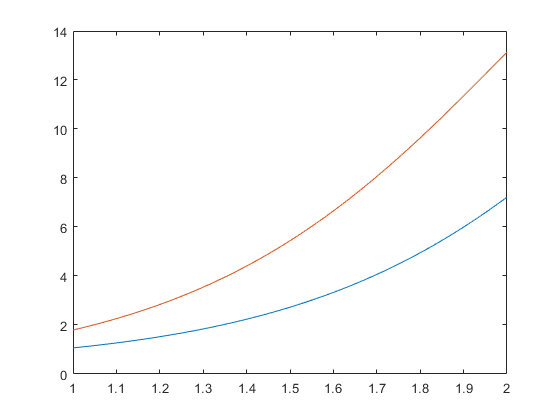

plot(x,g(x))
hold on
plot(x,d1g(x))
hold off



%E = (M*(b-a)*h^2)/12 escrever latex
%rearanjado
h = sqrt(12*E/M)

h =    0.003265986323711


### Definição de Funções


%Calculo do integral pela regra de Simpson Composta
function [res, h] = Simpcomp(f,a,b,n)
if mod(n,2) ~=0 %requer número de intervalos pares
    n = n+1;
end
h = abs(a-b)/n;
int = linspace(a,b,n+1);
res = (h/3)*(f(int(1))+f(int(end)));
for i = 2:1:n     %só os pontos interiores
    if mod(i,2) == 0    %a contagem no matlab começa no 1 por isso está trocado
        res = res + (4*h/3)*f(int(i));    %termos ímpares
    else
        res = res + (2*h/3)*f(int(i));    %termos pares
    end
end
end

%Calculo do integral pela regra dos Trapézios Composta
function [res,h] = Trapcomp(f,a,b,n)
int = linspace(a,b,n+1);
h = abs(a-b)/n;
res = 0;
for i = 1:1:n
    res = res + (f(int(i))+f(int(i+1))).*h/2;
end
end

%Função dos mínimos quadrados para 2 funções de base
function v = minq2(t,ft,phi0,phi1)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t))];
v = A\b;
end

%Função dos mínimos quadrados para 3 funções de base
function v = minq3(t,ft,phi0,phi1,phi2)
A = [dot(phi0(t),phi0(t)) dot(phi0(t),phi1(t)) dot(phi0(t),phi2(t));
     dot(phi1(t),phi0(t)) dot(phi1(t),phi1(t)) dot(phi1(t),phi2(t));
     dot(phi2(t),phi0(t)) dot(phi2(t),phi1(t)) dot(phi2(t),phi2(t))];
b = [dot(ft,phi0(t));
     dot(ft,phi1(t));
     dot(ft,phi2(t))];
v = A\b;
end

%Função produto interno
function [c] = dot(a,b)
n = numberofelements(a);
c = 0;
for i = 1:1:n
    c = c + a(i)*b(i);
end
end

%Função que encontra uma aproximação para um dado t recorrendo ao spline linear
function [b] = getvalue(t,ft,a)
n = numel(t);      
min = t(1);     %encontrar entre que pontos está o 'a' pedido
for i = 1:1:n
    if t(i) > a
        min = t(i-1);
        max = t(i);
        break
    end
end
b =  ft(min)+(ft(max)-ft(min)).*(a-min)./(max-min);
end

%Função que desenha o spline linear
function [] = splinelinear(t,ft)
scatter(t,ft)
hold on
x = linspace(1,12,100);
n = numel(t);
for i = 1:1:n-1
    s = @(x) ft(i)+(ft(i+1)-ft(i)).*(x-t(i))./(t(i+1)-t(i));
    fplot(s,[t(i),t(i+1)])
end
hold off
end